%Solving hard margin svm using CVX

clc;
clear all;
close all;
 
A = [0 0;2 0; 2 2;0 2;2.5 2.5;2.6 2.4; 3 3;4 3;4 4;3 4]; % data points
nc = 5; % amount of data to be assigned to each class
d = [-1*ones(nc,1);ones(nc,1)]; % class labels
D = diag(d); % diagonal matrix of class labels
n = size(A,2);
m = size(A,1);

e = ones(m,1);

cvx_begin quiet
 variables w(n) g
 dual variable u
 minimize (0.5*w'*w) % objective function
 subject to % constraints
 u:D*(A*w-g) >= e; 
cvx_end 
w

w =    16.6667
   -3.3333


u %lagrangian multipliers

u =     0.0000
    4.4444
    0.0000
    0.0000
  140.0002
  144.4446
    0.0000
    0.0000
    0.0000
    0.0000


idx = [find(u>0.1)] % finding indices of u>0

idx =      2
     5
     6


%respective active constraints
syms a b c
for i = 1:length(idx)
    k = idx(i);
    if u(k) ~=0
        d(k)*(A(k,1)*a + A(k,2)*b - c) >=1
    end
end

$$ans = 1\leq c-2\,a$$

$$ans = 1\leq c-\frac{5\,b}{2}-\frac{5\,a}{2}$$

$$ans = 1\leq \frac{13\,a}{5}+\frac{12\,b}{5}-c$$


% testing 
z = sign(A*w-g) % predicted class labels

z =     -1
    -1
    -1
    -1
    -1
     1
     1
     1
     1
     1


r = sum(d==z) % finding errors in predection

r = 10

Acc = (r/m)*100 % calculating accuracy 

Acc = 100

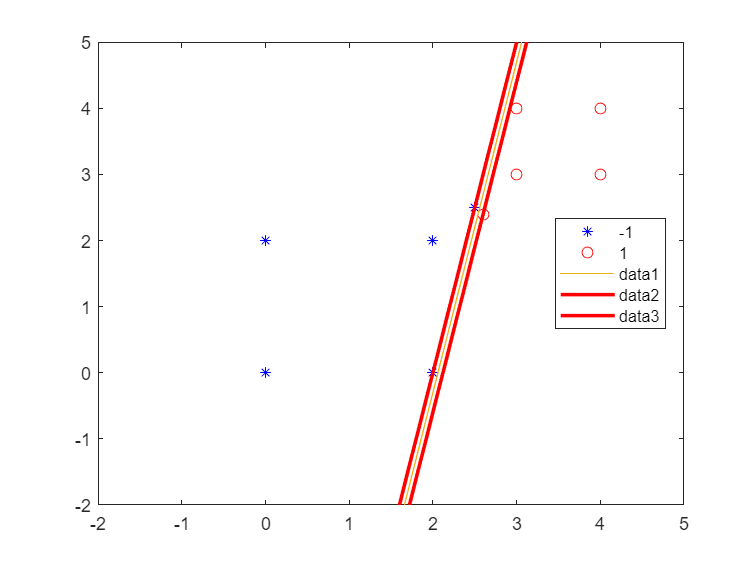


%visulaisation
figure;
gscatter(A(:,1),A(:,2),d,'br','*o');hold on
% linear classifier
x1 = -2:5; 
y1 = (g - w(1)*x1)/w(2);
plot(x1,y1);hold on; 

% boundary lines
x3 = (1 + g - w(1)*x1)/w(2);
plot(x1,x3,'r','linewidth',2);hold on;

x4 = (-1 + g - w(1)*x1)/w(2);
plot(x1,x4,'r','linewidth',2);
axis([-2 5 -2 5])
hold off

%Solving soft margin svm using CVX
clc;
clear all;
close all;
 
A = [0 0;2 0; 2 2;0 2;2.5 2.5;2.6 2.4; 3 3;4 3;4 4;3 4]; % 10 data points
nc = 5; % no of data per class
d = [-1*ones(nc,1);ones(nc,1)]; % class labels
D = diag(d); % diagonal matrix
n = size(A,2);
m = size(A,1);

e = ones(m,1);
%change values of 'c' and check hyperplane plot for each value.
c = 10; % control parameter
cvx_begin quiet
 variables w(n) g Psi(m) 
 dual variable u
 minimize ((0.5*w'*w)+(0.5*c*sum(Psi.^2))) % objective function
 subject to % constraints
 u:D*(A*w-g)+Psi >= e; 
 Psi >= 0;
cvx_end 
w

w =     1.7345
    0.1056


u %lagrangian multipliers

u =     0.0000
    0.0000
    0.4223
    0.0000
    9.6229
    8.7481
    1.1765
    0.0000
    0.0000
    0.1207


idx = [find(u>0.1)] % finding indices for u>0

idx =      3
     5
     6
     7
    10


%respective active constraints
syms a b c p
for i = 1:length(idx)
    k = idx(i);
    if u(k) ~=0
        d(k)*(A(k,1)*a + A(k,2)*b - c + p) >=1
    end
end

$$ans = 1\leq c-2\,b-2\,a-p$$

$$ans = 1\leq c-\frac{5\,b}{2}-\frac{5\,a}{2}-p$$

$$ans = 1\leq \frac{13\,a}{5}+\frac{12\,b}{5}-c+p$$

$$ans = 1\leq 3\,a+3\,b-c+p$$

$$ans = 1\leq 3\,a+4\,b-c+p$$


%testing
z = sign(A*w-g) % predicted class labels 

z =     -1
    -1
    -1
    -1
    -1
     1
     1
     1
     1
     1


r = sum(d==z) % finding errors in predection 

r = 10

Acc = (r/m)*100 % calculating accuracy 

Acc = 100

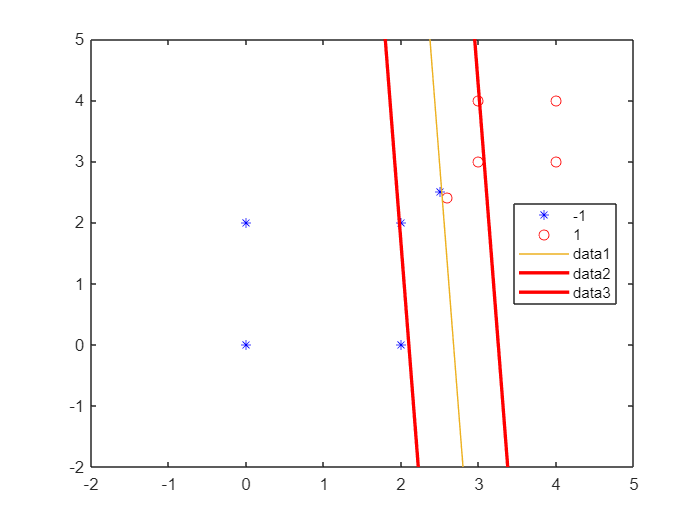


%visualization
figure;
gscatter(A(:,1),A(:,2),d,'br','*o');hold on
% linear classifier
x1 = -2:5; 
y1 = (g - w(1)*x1)/w(2);
plot(x1,y1);hold on;

%bounding lines
x3 = (1 + g - w(1)*x1)/w(2);
plot(x1,x3,'r','linewidth',2);hold on;
x4 = (-1 + g - w(1)*x1)/w(2);
plot(x1,x4,'r','linewidth',2);
axis([-2 5 -2 5])
hold off

%computation of gamma
clc;
clear all;
close all;
 
A = [0 0;2 0; 2 2;0 2;2.5 2.5;2.6 2.4; 3 3;4 3;4 4;3 4]; % 10 data points
nc = 5; % no of data per class
D = [-1*ones(nc,1);ones(nc,1)]; % class labels
%D = diag(d); % diagonal matrix

c = 10

c = 10


epsilon = 1e-3

epsilon = 1.0000e-03

Q = (A*A').*(D*D')

Q =          0         0         0         0         0         0         0         0         0         0
         0    4.0000    4.0000         0    5.0000   -5.2000   -6.0000   -8.0000   -8.0000   -6.0000
         0    4.0000    8.0000    4.0000   10.0000  -10.0000  -12.0000  -14.0000  -16.0000  -14.0000
         0         0    4.0000    4.0000    5.0000   -4.8000   -6.0000   -6.0000   -8.0000   -8.0000
         0    5.0000   10.0000    5.0000   12.5000  -12.5000  -15.0000  -17.5000  -20.0000  -17.5000
         0   -5.2000  -10.0000   -4.8000  -12.5000   12.5200   15.0000   17.6000   20.0000   17.4000
         0   -6.0000  -12.0000   -6.0000  -15.0000   15.0000   18.0000   21.0000   24.0000   21.0000
         0   -8.0000  -14.0000   -6.0000  -17.5000   17.6000   21.0000   25.0000   28.0000   24.0000
         0   -8.0000  -16.0000   -8.0000  -20.0000   20.0000   24.0000   28.0000   32.0000   28.0000
         0   -6.0000  -14.0000   -8.0000  -17.5000   17.4000   21.0000   24.0000   28.0

[m,n] = size(Q);

g = -ones(m,1);
LB = zeros(m,1);
UB = c*ones(m,1);
dt = D';
bequ = 0;
u = quadprog(Q,g,[],[],dt,bequ,LB,UB); %finding solution for 'u' using QP


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u

u =     0.0000
    0.0001
    0.9999
    0.0000
   10.0000
   10.0000
    0.9999
    0.0000
    0.0000
    0.0000


svind = find(u>epsilon) % points with u>0

svind =      3
     5
     6
     7


nsv = length(svind);
svmind = find((u>epsilon)&(u<(c-epsilon))) % support vectors on bounding plane

svmind =      3
     7


length(svmind);

gamma = sum((Q(svmind,svind)*u(svind).*D(svmind))-D(svmind))/length(svmind) %final gamma value

gamma = 5.0003